# ILLUSTRAZIONE GRAFICA DEL PUNTO DI BREAK EVEN

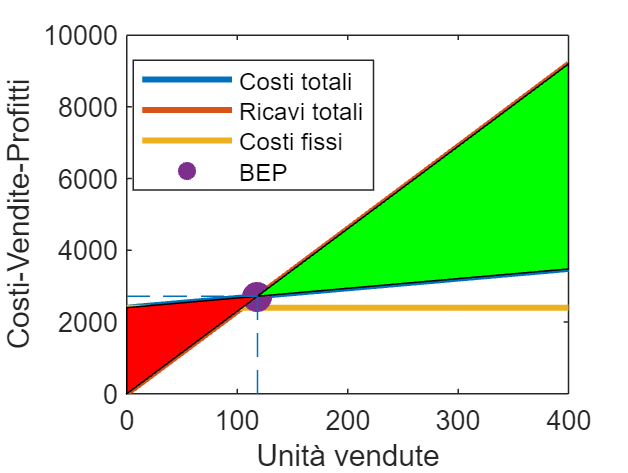


%unitVendute = unità vendute
unitVendute=(0:100:400)';

lwd=2;
% cv= costi variabili
costovariabile=2.7;
% prezzo unitario
prezzounitario=23;
costofisso=2400;
regioniColore=true;
aggiungicoord=true;

% CF = Costi fissi (non dipendono dalla quantità venduta)
CF=costofisso*ones(length(unitVendute),1);
% CT = Costi totali = Costi fissi + costi variabili
CT=CF+costovariabile*unitVendute;
% RT = ricavo totale = unità vendute * prezzo unitario
RT=unitVendute*prezzounitario;

X=[CT RT CF];
close all
hold('off')
plot(unitVendute,X,'LineWidth',lwd)
xlabel('Unità vendute')
ylabel('Costi-Vendite-Profitti')

% Risolvendo il sistema 2 equazioni
% RT=prezzouniario*x
% CT=costofisso+costovariabile*x
% Imponendo RT=CT si ottiene
% x= quantità venduta di break even 
%    = costofisso/(prezzounitario-costovariabile)
xbreakeven=costofisso/(prezzounitario-costovariabile);
% breakevenIn0400 = valore booleano che è vero se le quantittà di breakeven
% sono nell'intervallo 0 400
breakevenIn0400=xbreakeven>0 && xbreakeven<400;
if ~breakevenIn0400
    disp('Attenzione il punto di intersezione non è stato trovato')
    disp('nell''intervallo specificato di unità vendute')
    disp('E necessario aumentare il prezzo unitario o diminuire il costo fisso o quello variabile')
    suv=">400";
    hold('on')
    scatter(NaN,NaN)
else
    % Osservazione: in corrispondenza di xbreakeven
    % prezzounitario*xbreakeven = CF+costovariabile*xbreakeven
    ybreakeven=prezzounitario*xbreakeven;
    hold('on')
    % Aggiungo il punto di break even
    scatter(xbreakeven,ybreakeven,100,'filled')

    suv=string(xbreakeven);
    if regioniColore ==true
        % Riempi la regione relativa all'utile
        fill([xbreakeven;400;400],[ybreakeven;CT(end);RT(end)],'g')
        % Riempi la regione relativa alla perdita
        fill([0;xbreakeven;0],[0;ybreakeven;CT(1)],'r')
    end

    if aggiungicoord==true
        line([xbreakeven;xbreakeven],[0;ybreakeven],'LineStyle','--')
        line([0;xbreakeven],[ybreakeven;ybreakeven],'LineStyle','--')
    end
end
legend(["Costi totali" "Ricavi totali" "Costi fissi" "BEP" ],'Location','best');

disp('-----------------------')

-----------------------


disp("Unità da vendere per Break even="+suv)

Unità da vendere per Break even=118.2266


disp('----------------------')

----------------------
